clear all 
clc
path_f = 'C:\Users\Martha Ca$h\Desktop\School\Grad School\Research\DVBS2X Simulation\Equalization\BER Plot\';
filename = 'ber.xls';
ber = zeros(1, 26); 
i =1; 
for EbNo = -2:23
    disp(EbNo)
    tic
    sim('DVB_AWGN_MLSE',0.5);
    toc
    berVec(1)
    ber(i) = berVec(1); 
    i = i+1;
end 

Elapsed time is 126.011767 seconds.


ans = 0.3992

    -1



Elapsed time is 105.979027 seconds.


ans = 0.3863

     0



Elapsed time is 101.231406 seconds.


ans = 0.3705

     1



Elapsed time is 105.261191 seconds.


ans = 0.3538

     2



Elapsed time is 106.347830 seconds.


ans = 0.3350

     3



Elapsed time is 95.521369 seconds.


ans = 0.3143

     4



Elapsed time is 113.418998 seconds.


ans = 0.2916

     5



Elapsed time is 105.139372 seconds.


ans = 0.2682

     6



Elapsed time is 108.196060 seconds.


ans = 0.2443

     7



Elapsed time is 106.064256 seconds.


ans = 0.2196

     8



Elapsed time is 102.443111 seconds.


ans = 0.1952

     9



Elapsed time is 99.635239 seconds.


ans = 0.1715

    10



Elapsed time is 185.405611 seconds.


ans = 0.1486

    11



Elapsed time is 162.389435 seconds.


ans = 0.1263

    12



Elapsed time is 117.477459 seconds.


ans = 0.1049

    13



Elapsed time is 108.538873 seconds.


ans = 0.0845

    14



Elapsed time is 90.054349 seconds.


ans = 0.0654

    15



Elapsed time is 97.934846 seconds.


ans = 0.0484

    16



Elapsed time is 102.334318 seconds.


ans = 0.0335

    17



Elapsed time is 103.507568 seconds.


ans = 0.0219

    18



Elapsed time is 91.268969 seconds.


ans = 0.0130

    19



Elapsed time is 113.186854 seconds.


ans = 0.0072

    20



Elapsed time is 99.060422 seconds.


ans = 0.0034

    21



Elapsed time is 112.865453 seconds.


ans = 0.0014

    22



Elapsed time is 100.161464 seconds.


ans = 5.0352e-04

    23



Elapsed time is 109.760821 seconds.


ans = 1.3251e-04

writematrix(ber, [path_f,filename]);

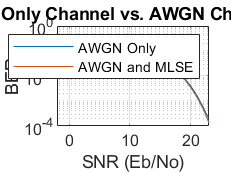

snr = -2:23; 
path_f = 'C:\Users\Martha Ca$h\Desktop\School\Grad School\Research\DVBS2X Simulation\Equalization\BER Plot\';
f = 'ber.xls';

path_og = 'C:\Users\Martha Ca$h\Desktop\School\Grad School\Research\DVBS2X Simulation\AWGN Model\BER Plot\';
f_og = 'ber.xls';

awgn = readmatrix([path_og, f_og]);

ber = readmatrix([path_f,filename]);
h = figure;
semilogy(snr, awgn); 
hold on 
semilogy(snr, ber);
grid on
title('BER: AWGN Only Channel vs. AWGN Channel with MLSE')
xlabel('SNR (Eb/No)');
ylabel('BER'); 
legend('AWGN Only', 'AWGN and MLSE');

savefig(h, [path_f, 'BER Plot']); 